EP1 - Modelos e suas respostas

s = tf('s');

Analisando G1

Vamos começar descobrindo o ganho. Como o ganho é o módulo da saída/entrada. Então temos que K = 3/1 = 3.

O valor de 63% de 3 é 1,89. Isso ocorre no tempo igual 5s.

então temos que G = 3/5s+1

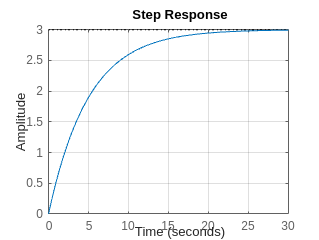

G1 = 3/(5*s+1);
step(G1); grid;

Como curiosidade. Você pode ignorar essa parte.

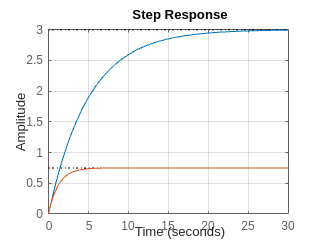

M1 = feedback(G1,1);
step(G1,M1); grid;

Analisando G2

Analogamente, o ganho K é 0,5/1 = 0,5

o tempo morto parece ser de 2s

a cte de tempo é o tempo depois que o sistema sai da inércia e chega em 63%, ou seja, cerca de 12 - 2 = 10s

então G2 é da forma:

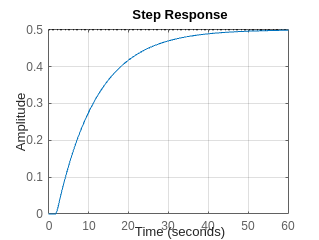

G2 = exp(-2*s)*0.5/(10*s+1);
step(G2); grid;

Analisando G3

MP = 40% → achamos z

A = (log(0.4)^2)/pi^2

A = 0.0851

z = sqrt(A/(A+1))

z = 0.2800

Com z e tp, achamos wn (frequência natural não amortecida)

tp = 2.5

tp = 2.5000

wn = pi/(tp*sqrt(1-z^2))

wn = 1.3090

Logo, temos G3

G3 = wn^2 / (s^2 + 2*z*wn*s + wn^2)

G3 =
 
          1.713
  ---------------------
  s^2 + 0.733 s + 1.713
 
Continuous-time transfer function.
Model Properties


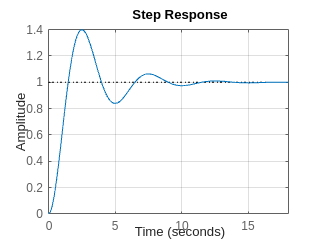

step(G3); grid;

Está suficientemente próxima.

EP1.b

Analisando G1

MP = 70% → acha o z

mp = 0.72

mp = 0.7200

A = (log(mp)/pi)^2

A = 0.0109

z = sqrt(A/(A+1))

z = 0.1040

com z e tp, temos wn;

tp = 1.5

tp = 1.5000

wn = pi/(tp*sqrt(1-z^2))

wn = 2.1058

logo, g1 é

g1 = wn^2 / (s^2 + 2*wn*z*s + wn^2)

g1 =
 
          4.434
  ---------------------
  s^2 + 0.438 s + 4.434
 
Continuous-time transfer function.
Model Properties


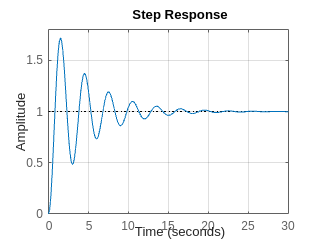

step(g1); grid;

Analisando G2

analogamente, k = 2/1 = 2; cte t = 8s para chegar em 63% (1.2)

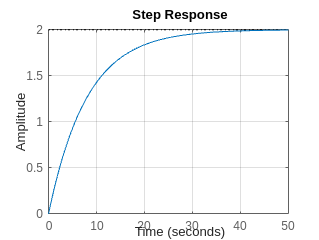

k = 2;
cte_t = 8;
G2 = k/(cte_t*s + 1);
step(G2); grid;

Analisando G3

analogamente, k = 0.2/1 = 0.2, cte_t = 25s para chegar em 63% (0.12), delay = 8s

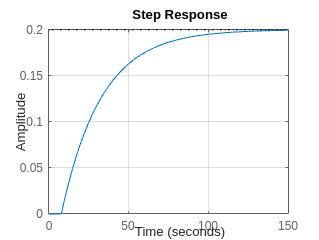

k = 0.2;
cte_t = 25;
delay = 8;
G3 = k*exp(-delay*s)/(cte_t*s + 1);
step(G3); grid;